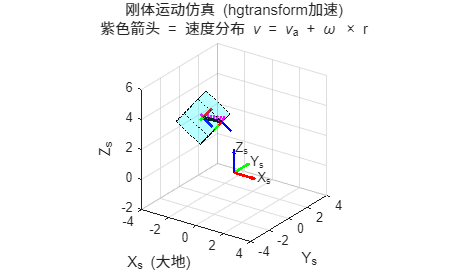

%% 刚体自由运动及速度场可视化 (单脚本版)

% 包含：大地坐标系(S)、刚体中心(A)、刚体角点(B)、AB连线及速度场
clc; clear; close all;

%% 1. 初始化绘图环境
figure('Color', 'white', 'Name', '刚体运动与速度场', 'NumberTitle', 'off');
axis equal; grid on; hold on;
xlabel('X_s (大地)'); ylabel('Y_s'); zlabel('Z_s');
title({'刚体运动仿真 (单脚本)', '紫色箭头表示连线 AB 上的速度分布 \nu = \nu_a + \omega \times r','注意此处的速度不是旋量速度'});
view(35, 25);
xlim([-4 4]); ylim([-4 4]); zlim([-2 6]); % 稍微调整视野适应向上运动
set(gca, 'FontSize', 10);

%% 2. 绘制大地坐标系 S (静态)
% 红色X，绿色Y，蓝色Z
quiver3(0,0,0, 1.5,0,0, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0,0,0, 0,1.5,0, 0, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0,0,0, 0,0,1.5, 0, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5);
text(1.6,0,0, 'X_s'); text(0,1.6,0, 'Y_s'); text(0,0,1.6, 'Z_s');

%% 3. 定义刚体数据
L = 1; % 半边长
% 局部顶点 (8个点)
local_verts = [ -L -L -L;  L -L -L;  L  L -L; -L  L -L;
                -L -L  L;  L -L  L;  L  L  L; -L  L  L ]'; 
% 面连接关系
faces = [1 2 3 4; 2 6 7 3; 4 3 7 8; 5 8 7 6; 1 5 6 2; 1 4 8 5];

% A系(中心) 和 B系(角点) 的局部偏移
offset_a_local = [0; 0; 0];
offset_b_local = [L; L; L]; 
% B系相对于刚体的局部旋转 (绕Z轴转45度)
theta_b = deg2rad(90);
R_b_local = [cos(theta_b) -sin(theta_b) 0; sin(theta_b) cos(theta_b) 0; 0 0 1];

%% 4. 初始化图形句柄 (创建空对象，稍后在循环中更新)

% 4.1 刚体 (透明立方体)
h_cube = patch('Vertices', local_verts', 'Faces', faces, ...
               'FaceColor', 'cyan', 'FaceAlpha', 0.15, ...
               'EdgeColor', 'k', 'LineStyle', ':');

% 4.2 坐标系 A (随动，显示在刚体中心)
h_ax = line([0 0], [0 0], [0 0], 'Color', 'r', 'LineWidth', 2);
h_ay = line([0 0], [0 0], [0 0], 'Color', 'g', 'LineWidth', 2);
h_az = line([0 0], [0 0], [0 0], 'Color', 'b', 'LineWidth', 2);

% 4.3 坐标系 B (随动，显示在刚体角点)
h_bx = line([0 0], [0 0], [0 0], 'Color', 'r', 'LineWidth', 1.5);
h_by = line([0 0], [0 0], [0 0], 'Color', 'g', 'LineWidth', 1.5);
h_bz = line([0 0], [0 0], [0 0], 'Color', 'b', 'LineWidth', 1.5);

% 4.4 连接线 AB
h_line_ab = line([0 0], [0 0], [0 0], 'Color', 'k', 'LineWidth', 2.5);

% 4.5 速度场箭头 (Quiver对象)
% 在AB线上取点绘制速度矢量
h_quiver = quiver3(0,0,0,0,0,0, 'Color', 'm', 'LineWidth', 1.5, 'AutoScale', 'off');

%% 5. 动画仿真循环
dt = 0.02;
t_total = 20;

% 用于数值差分计算速度的变量
T_prev = [0;0;0];
R_prev = eye(3);
is_first_frame = true;

for t = 0:dt:t_total
    %% --- A. 运动学计算 (位置 T 和 姿态 R) ---
    % 1. 平动：螺旋上升
    T_curr = [2*sin(0.5*t); 2*cos(0.5*t); 0.3*t - 2];
    
    % 2. 转动：欧拉角随时间变化
    yaw = 0.5 * t;   % 绕Z
    pitch = 0.2 * t; % 绕Y
    roll = 0.3 * t;  % 绕X
    
    R_z = [cos(yaw) -sin(yaw) 0; sin(yaw) cos(yaw) 0; 0 0 1];
    R_y = [cos(pitch) 0 sin(pitch); 0 1 0; -sin(pitch) 0 cos(pitch)];
    R_x = [1 0 0; 0 cos(roll) -sin(roll); 0 sin(roll) cos(roll)];
    R_curr = R_z * R_y * R_x; % 当前姿态矩阵
    
    %% --- B. 动力学计算 (速度 v 和 角速度 omega) ---
    if is_first_frame
        v_linear = [0;0;0];
        omega = [0;0;0];
        is_first_frame = false;
    else
        % 线速度 v = dP/dt
        v_linear = (T_curr - T_prev) / dt;
        
        % 角速度 omega 计算: [omega]x = R_dot * R'
        R_dot = (R_curr - R_prev) / dt;
        W_skew = R_dot * R_curr'; 
        omega = [W_skew(3,2); W_skew(1,3); W_skew(2,1)];
    end
    % 更新历史状态
    T_prev = T_curr;
    R_prev = R_curr;
    
    %% --- C. 更新图形对象 ---
    
    % 1. 更新立方体顶点
    % Global_Verts = R * Local_Verts + T
    verts_global = R_curr * local_verts + repmat(T_curr, 1, 8);
    set(h_cube, 'Vertices', verts_global');
    
    % 2. 计算 A 系和 B 系的原点和基向量
    % A系 (中心)
    Origin_A = T_curr + R_curr * offset_a_local;
    Axes_A = R_curr * eye(3) * 0.8; % 轴长0.8
    
    % B系 (角点)
    Origin_B = T_curr + R_curr * offset_b_local;
    R_B_global = R_curr * R_b_local; % B系姿态 = 刚体姿态 * B相对刚体姿态
    Axes_B = R_B_global * eye(3) * 0.8; % 轴长0.6
    
    % 3. 绘制/更新坐标轴 (手动更新6条线)
    % A系更新
    set(h_ax, 'XData', [Origin_A(1), Origin_A(1)+Axes_A(1,1)], 'YData', [Origin_A(2), Origin_A(2)+Axes_A(2,1)], 'ZData', [Origin_A(3), Origin_A(3)+Axes_A(3,1)]);
    set(h_ay, 'XData', [Origin_A(1), Origin_A(1)+Axes_A(1,2)], 'YData', [Origin_A(2), Origin_A(2)+Axes_A(2,2)], 'ZData', [Origin_A(3), Origin_A(3)+Axes_A(3,2)]);
    set(h_az, 'XData', [Origin_A(1), Origin_A(1)+Axes_A(1,3)], 'YData', [Origin_A(2), Origin_A(2)+Axes_A(2,3)], 'ZData', [Origin_A(3), Origin_A(3)+Axes_A(3,3)]);
    
    % B系更新
    set(h_bx, 'XData', [Origin_B(1), Origin_B(1)+Axes_B(1,1)], 'YData', [Origin_B(2), Origin_B(2)+Axes_B(2,1)], 'ZData', [Origin_B(3), Origin_B(3)+Axes_B(3,1)]);
    set(h_by, 'XData', [Origin_B(1), Origin_B(1)+Axes_B(1,2)], 'YData', [Origin_B(2), Origin_B(2)+Axes_B(2,2)], 'ZData', [Origin_B(3), Origin_B(3)+Axes_B(3,2)]);
    set(h_bz, 'XData', [Origin_B(1), Origin_B(1)+Axes_B(1,3)], 'YData', [Origin_B(2), Origin_B(2)+Axes_B(2,3)], 'ZData', [Origin_B(3), Origin_B(3)+Axes_B(3,3)]);
    
    % 4. 更新连线 AB
    set(h_line_ab, 'XData', [Origin_A(1) Origin_B(1)], ...
                   'YData', [Origin_A(2) Origin_B(2)], ...
                   'ZData', [Origin_A(3) Origin_B(3)]);
               
    % 5. 计算并更新速度场 (核心部分)
    % 在 AB 线段上取 8 个采样点
    num_samples = 8;
    s_param = linspace(0, 1, num_samples);
    P_samples = zeros(3, num_samples);
    V_samples = zeros(3, num_samples);
    
    for k = 1:num_samples
        % 当前采样点位置 (线性插值)
        P_k = Origin_A + s_param(k) * (Origin_B - Origin_A);
        P_samples(:, k) = P_k;
        
        % 速度计算: v_k = v_a + omega x r_ak
        r_ak = P_k - Origin_A; % 从转动中心指向采样点的向量
        v_rot = cross(omega, r_ak);
        V_samples(:, k) = v_linear + v_rot;
    end
    
    % 更新 Quiver 数据
    scale = 0.3; % 缩小箭头比例，避免太长
    set(h_quiver, 'XData', P_samples(1,:), 'YData', P_samples(2,:), 'ZData', P_samples(3,:), ...
                  'UData', V_samples(1,:)*scale, ...
                  'VData', V_samples(2,:)*scale, ...
                  'WData', V_samples(3,:)*scale);

    drawnow ;
    pause(0.02); % 如果电脑太快可以取消注释这行
    
end